clear all;
close all;
clc

Synthesis

% Given parameters
l4 = 50; % Input: length of rocker O4B
target_swing = 180; % Input: Extreme angle in degrees
O4x = 0; O4y = 0; % Start with O4 at origin
delta = 40; % Input: quick return ratio
delta_tolerance = 2; % Allowed deviation from target delta (quick return ratio)
swing_tolerance = 2; % Allowed deviation from target swing angle in degrees
path_tolerance = 1; % Allowed deviation from target circular path

% Calculate B1 and B2 positions based on rocker length and swing angle
B2x = O4x + l4 * cosd(90 - target_swing / 2);
B2y = O4y + l4 * sind(90 - target_swing / 2);
B1x = O4x - l4 * cosd(90 - target_swing / 2);
B1y = O4y + l4 * sind(90 - target_swing / 2);

Optimization (Iteration)

% Initialize result variables
best={};
% Loop over possible positions for O2
for degree_B2O2 = 0:1:180 % Loop the degree of O2B2
    for B2O2 = ((B2x - B1x) / cosd(degree_B2O2)):1:200
        % Determine O2 coordinates
        O2x = B2x - B2O2 * cosd(degree_B2O2);
        O2y = B2y - B2O2 * sind(degree_B2O2);
        
        % Calculate quick return ratio check (delta)
        delta_x = abs(B1x - O2x);
        delta_y = abs(B1y - O2y);
        err = abs(atand(delta_y/delta_x)-delta-degree_B2O2);
        
        % Check quick return condition within tolerance
        if err <= delta_tolerance
            % Calculate link lengths
            l1 = sqrt((O4x - O2x)^2 + (O4y - O2y)^2);
            B1O2 = sqrt(delta_x^2 + delta_y^2);
            l2 = (B2O2 - B1O2) / 2;
            if B1O2 + l2 == B2O2 - l2
                l3 = B1O2 + l2;
                lengths = sort([l1, l2, l3, l4]);
                % Verify Grashof’s condition
                 if lengths(1) + lengths(4) < lengths(2) + lengths(3) && lengths(1) == l2 % Check shortest link
                     achievable_swing = 2 * acosd((l1^2 + l4^2 - l3^2 - l2^2) / (2 * l1 * l4));
                     check = 0; % For checking the possibility of mechanism
                     for theta = 1:1:179
                         x = l4 * cosd(theta);
                         y = l4 * sind(theta);
                         if sqrt((O2x-x)^2+(O2y-y)^2) - (l2+l3) > path_tolerance
                             check = 1;
                         end
                     end
                     if check == 0
                         best{end+1} = {round(l1,2) , round(l2,2) , round(l3,2) , round(O2x,2) , round(O2y,2) , err , achievable_swing,degree_B2O2};
                     end
                 end
            end
        end
    end
end
%find min err
min_err = zeros(1,length(best));
for i = 1:length(best)
    min_err(i) = abs(best{i}{end-2});
    best{i}{end};
end
min_err

min_err =     0.2543    0.5851    0.8260    1.4098    0.0534    1.8171    1.0960    0.6211


[M I] = min(min_err);
%I = 3
best_l1 = best{I}{1}; best_l2 = best{I}{2}; best_l3 = best{I}{3}; best_O2x = best{I}{4}; best_O2y = best{I}{5}; best_degree_B2O2 = best{I}{end};
best{I}{end-1};

% Change the position (Swap O2 to origin)
O4x = -best_O2x; O4y = -best_O2y;
O2x = 0; O2y = 0;
l1 = best_l1; l2 = best_l2; l3 = best_l3;

% Display results
if l1 ~= 0
    fprintf('Optimized lengths and position for 180-degree crank-rocker:\n');
    fprintf('Ground (l1): %.2f\n', l1);
    fprintf('Crank (l2): %.2f\n', l2);
    fprintf('Coupler (l3): %.2f\n', l3);
    fprintf('Rocker (l4): %.2f\n', l4);
    fprintf('O4 position: (%.2f, %.2f)\n', O4x,O4y);
else
    disp('No solution found that satisfies the 180-degree swing requirement.');
end

Optimized lengths and position for 180-degree crank-rocker:


Ground (l1): 64.41


Crank (l2): 47.41


Coupler (l3): 66.34


Rocker (l4): 50.00


O4 position: (62.90, 13.86)


Setting the variables

theta2 = sym('theta_2'); % Angle between link 2 and ground in rad
theta3 = sym('theta_3'); % Angle between link 3 and ground in rad
theta4 = sym('theta_4'); % Angle between link 4 and ground in rad

Set up constraints (Change O2 to origin)

ext_length = 60; % Give the extender length to solar panel
sideway = 100; % Solar Panel

Equation of Motions

Ax = O2x + l2*cos(theta2);
Ay = O2y + l2*sin(theta2);
Bx = O4x + l4*cos(theta4);
By = O4y + l4*sin(theta4);

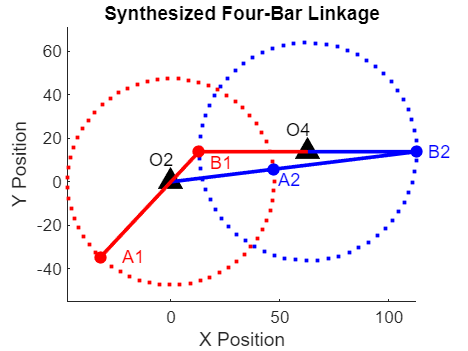

% Plot the four-bar linkage
figure()
hold on
plot(O2x,O2y,"^k")
plot(O4x,O4y,"^k")
plot(subs(Ax,0:0.1:2*pi),subs(Ay,0:0.1:2*pi),".r")
plot(subs(Bx,0:0.1:2*pi),subs(By,0:0.1:2*pi),".b")
axis equal

% Plot O4 and O2
plot(O2x,O2y,"^k", 'LineWidth', 4)
plot(O4x,O4y,"^k", 'LineWidth', 4)

% Point A
phi = best_degree_B2O2;
zeta = 180 + phi + delta - M;
A1x = O2x + l2 * cosd(zeta);
A1y = O2y + l2 * sind(zeta);
A2x = O2x + l2 * cosd(phi);
A2y = O2y + l2 * sind(phi);
plot(A1x, A1y, '.r', 'MarkerSize',20) % Point A1
plot(A2x, A2y, '.b', 'MarkerSize',20) % Point A2

% Plot crank (O2 to A)
plot([O2x, A1x], [O2y, A1y], '-r', 'LineWidth', 2) % Extreme Left
plot([O2x, A2x], [O2y, A2y], '-b', 'LineWidth', 2) % Extreme Right

% Point A
B2x = O4x + l4 * cosd(90 - target_swing / 2);
B2y = O4y + l4 * sind(90 - target_swing / 2);
B1x = O4x - l4 * cosd(90 - target_swing / 2);
B1y = O4y + l4 * sind(90 - target_swing / 2);
plot(B1x, B1y, '.r', 'MarkerSize',20) % Point B1
plot(B2x, B2y, '.b', 'MarkerSize',20) % Point B2

% Plot rocker (O4 to B)
plot([O4x, B1x], [O4y, B1y], '-r', 'LineWidth', 2) % Extreme Left
plot([O4x, B2x], [O4y, B2y], '-b', 'LineWidth', 2) % Extreme Right

% Plot coupler (A to B)
plot([A1x, B1x], [A1y, B1y], '-r', 'LineWidth', 2) % Extreme Left
plot([A2x, B2x], [A2y, B2y], '-b', 'LineWidth', 2) % Extreme Right

% Labels and plot settings
title('Synthesized Four-Bar Linkage');
xlabel('X Position');
ylabel('Y Position');
text(O2x-10,O2y+10,'O2','FontSize', 10, 'Color','k')
text(O4x-10,O4y+10,'O4','FontSize', 10, 'Color','k')
text(A1x+10,A1y,'A1','FontSize', 10, 'Color','r')
text(A2x+2,A2y-5,'A2','FontSize', 10, 'Color','b')
text(B1x+5,B1y-5,'B1','FontSize', 10, 'Color','r')
text(B2x+5,B2y,'B2','FontSize', 10, 'Color','b')

hold off;

Eliminate the excess variables

eq1 = Bx == Ax + l3*cos(theta3);
eq2 = By == Ay + l3*sin(theta3);

% Write theta4 in term of theta 2
sol = solve([eq1 eq2],[theta3 theta4]);
theta4_sol = sol.theta_4(1);
theta3_sol = sol.theta_3(1);

% Check the variable of A and B
symvar([Ax Ay])

$$ans = \theta_{2}$$

symvar([Bx By])

$$ans = \theta_{4}$$


% Change the variable of B from theta 4 to theta 2
BxNew = subs(Bx,theta4,theta4_sol);
ByNew = subs(By,theta4,theta4_sol);
symvar([BxNew ByNew])

$$ans = \theta_{2}$$

Base of Solar Cell Link

%Calculate the extender to Solar Base
Px = BxNew + ext_length * cos(theta4_sol);
Py = ByNew + ext_length * sin(theta4_sol);

% Calculate direction of link B
dx = l4 * cos(theta4_sol);
dy = l4 * sin(theta4_sol);

% Normalize the direction vector to get the unit vector
linkB_mag = sqrt(dx^2 + dy^2);
unit_B = [dx / linkB_mag, dy / linkB_mag];

% Get the left and right perpendicular unit vectors
perp_left = [-unit_B(2), unit_B(1)]; % 90 degrees left
perp_right = [unit_B(2), -unit_B(1)]; % 90 degrees right

%Calculate the base of Solar cell
Qx = Px + sideway * perp_left(1); 
Qy = Py + sideway * perp_left(2);
Rx = Px + sideway * perp_right(1); 
Ry = Py + sideway * perp_right(2); 

Animation

% Plot the animation with extreme positions
h_link2 = @(t) plot([O2x subs(Ax,t)], [O2y subs(Ay,t)], '-', 'Color', '#EDB120', 'LineWidth', 2);
h_link4 = @(t) plot([O4x subs(BxNew,t) subs(Px,t) subs(Qx,t) subs(Rx,t)], ...
                    [O4y subs(ByNew,t) subs(Py,t) subs(Qy,t) subs(Ry,t)], "-k", 'LineWidth', 2);
h_link3 = @(t) plot([subs(Ax,t) subs(BxNew,t)], [subs(Ay,t) subs(ByNew,t)], "-g", 'LineWidth', 2);

h_r1 = @(~) plot([O4x B1x], [O4y B1y], "-r", 'LineWidth', 1);
h_r2 = @(~) plot([O4x B2x], [O4y B2y], "-r", 'LineWidth', 1);

figure()
hold on
plot(O2x,O2y,"^k")
plot(O4x,O4y,"^k")
plot(subs(Ax,0:0.1:2*pi),subs(Ay,0:0.1:2*pi),'--', 'Color', '#EDB120')
plot(subs(Bx,0:0.1:2*pi),subs(By,0:0.1:2*pi),"--k")

% Plot extreme positions of rocker
plot(B1x, B1y, "xr", 'MarkerSize', 10, 'LineWidth', 1.5);
plot(B2x, B2y, "xr", 'MarkerSize', 10, 'LineWidth', 1.5);

fanimator(h_link2)
fanimator(h_link3)
fanimator(h_link4)
fanimator(h_r1);
fanimator(h_r2);
hold off

axis equal

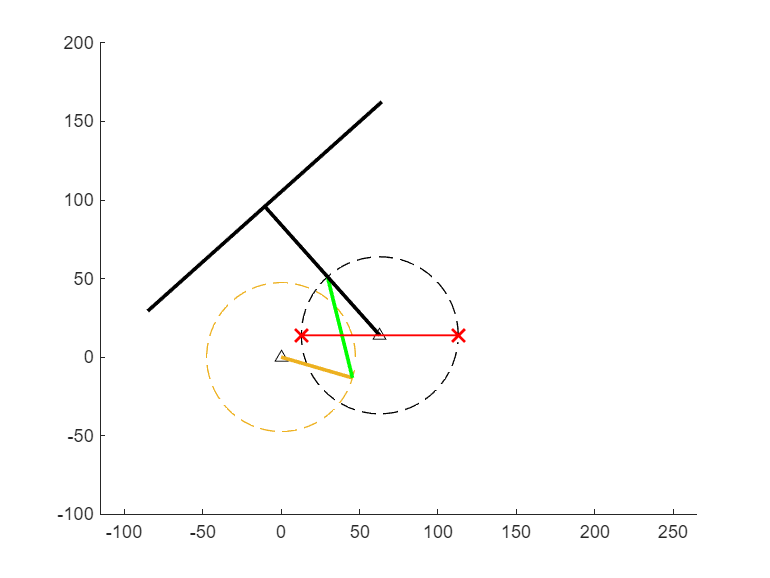

playAnimation

Velocity Analysis

r_O2A = [Ax Ay 0] - [O2x O2y 0]; % Vector from O2 to A
r_AB = [BxNew ByNew 0] - [Ax Ay 0]; % Vector from A to B

% Calculate omega 2,3
omega2 = -pi/(12*60*60);
omega3 = omega2*diff(theta3_sol,theta2);

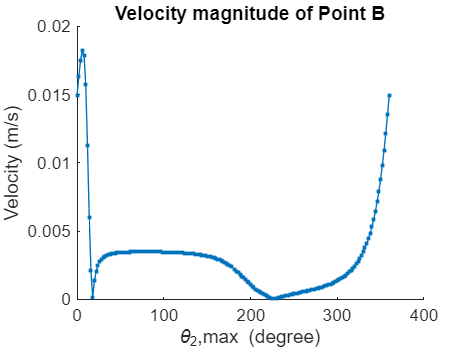

% Find velocity of point A and point P
va = cross([0 0 omega2],r_O2A);
vb = va + cross([0 0 omega3],r_AB);

% Calculate Vb at every theta
Abs_Vb = [];
theta_Vb = [];
for k = 0:2:360   
    Vb = subs(vb,theta2,deg2rad(k));    
    theta = rad2deg(atan(Vb(2),Vb(1)));
    theta_Vb(end+1) = theta;
    abs_Vb = sqrt(Vb(1)^2 + Vb(2)^2);
    Abs_Vb(end+1) = abs_Vb;
end

figure()
hold on
title('Velocity magnitude of Point B')
xlabel('\theta_2,max (degree)') 
ylabel('Velocity (m/s)') 
t = 0:2:360;
plot(t,Abs_Vb,'.-')
hold off

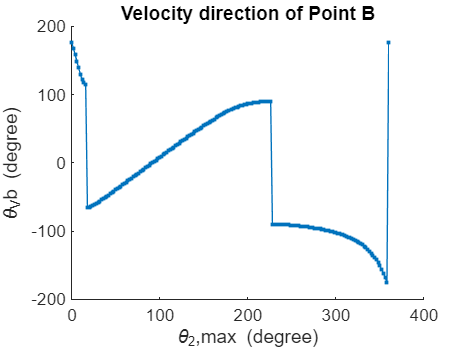


figure()
hold on
title('Velocity direction of Point B')
xlabel('\theta_2,max (degree)') 
ylabel('\theta_Vb (degree)') 
t = 0:2:360;
plot(t,theta_Vb,'.-')
hold off